# `DEMO_03a:`   4-bar linkage parameters for Simulink** KINEMATIC **`simulation`

In this example, we'll explore a Simulink/Simscape model of a 4bar mechanism.  Specifically we'll use the Simulink model to do **a kinematic simulation** of the mechanism.

## ***ATTENTION***:

- Make your selections from the interactive dropboxes shown below ... and then run this script 

**Figure 01:  the 4bar linkage**

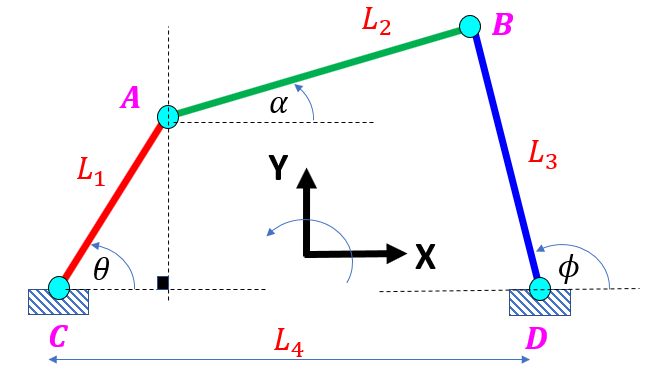

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

## Define the geometry and initial pose - part 1

 Make your choices from the list boxes below .***.. and then run this script***

Do you want to use a preconfigured machine ?

tf_use_preconfig_machine       = true;

If so, select one and run the script

the_preconfig_MACHINE_ID = "MACHINE_A";

If you don't want to explore a preconfigured machine, then define the link lengths yourself.

- ***TIP:  ****have you already seen the machine using the APP  *`>> bh_4bar_explore_app`

if(true==tf_use_preconfig_machine)
    [L1, L2, L3, L4] = bh_get_preconfigured_machine(the_preconfig_MACHINE_ID);
else
   % specify your own machine
   L1        = 0.399;   % m
   L2        = 1;   % m
   L3        = 0.4;   % m
   L4        = 1;     % m
end

## Define the geometry and initial pose - part 2

The INITIAL conditions for $\theta$ and $\theta^˙$:

theta           = 30;             % degs
theta_0_rad     = deg2rad(theta); % rad
theta_dot_0_rad = pi*30/180;      % rad/sec

Confirm that the machine is a CRANK machine:

OBJ_kin = bh_4bar_kin_CLS(L1, L2, L3, L4, theta_0_rad);

if(~OBJ_kin.is_crank_machine )
    fprintf('\n This is either an INVALID machine ... OR');
    fprintf('\n the machine has *some* bad Z-roots  ... OR');
    fprintf('\n the input link(L1) canNOT be fully rotated through 360 degrees');    
    fprintf('\n Consult the bh_4bar_explore_app APP to explore.');
    error("###_ERROR:  we only want CRANK machines for these simulations !")
end

View the machine:

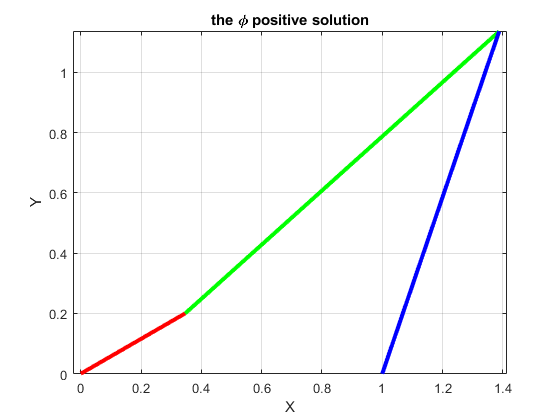

OBJ_kin.plot_phi_pos();

Extract the link angles - we'll use the configuration where the initial value of $\phi$is positive

[phi_rad, alpha_rad] = OBJ_kin.get_phi_alpha(theta_0_rad)

phi_rad = 1.2416

alpha_rad = 0.7319

And display these in degrees:

rad2deg([phi_rad, alpha_rad])

ans =    71.1406   41.9336


## Define parameters needed by Simscape model:

density = 1000; % kg/m3
H       = L1/10;  % m
W       = L1/100; % m 
g       = 9.81;   % m/s^2

The INITIAL joint angles:

joints.C.ang_degs = rad2deg(theta_0_rad);
joints.C.vel_degs = rad2deg(theta_dot_0_rad);
joints.D.ang_degs = rad2deg(phi_rad);

## Define parameters needed by the Hand derivation:

The mass and inertias of the members:

m1 =  LOC_calc_mass(L1, H, W, density);
m2 =  LOC_calc_mass(L2, H, W, density);
m3 =  LOC_calc_mass(L3, H, W, density);

I_G1 = LOC_calc_IG(L1, H, W, density);
I_G2 = LOC_calc_IG(L2, H, W, density);
I_G3 = LOC_calc_IG(L3, H, W, density);

## Open the Simulink model for simulation model:

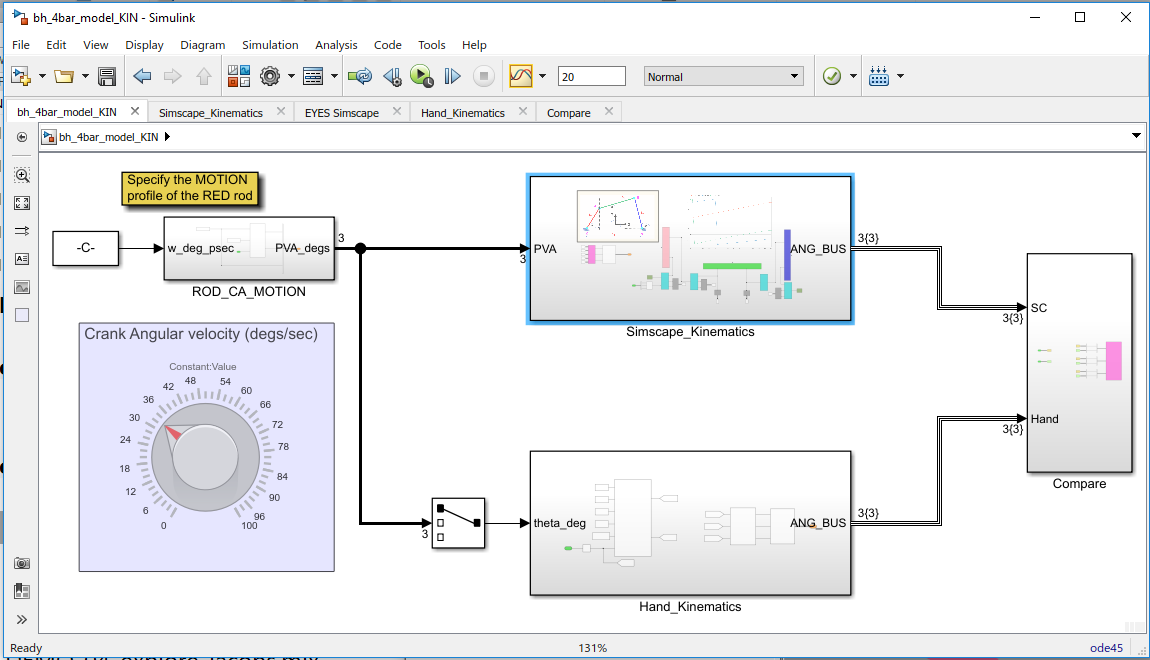

open_system('bh_4bar_model_KIN');

 To run the simulation click the "Run" button in the model:

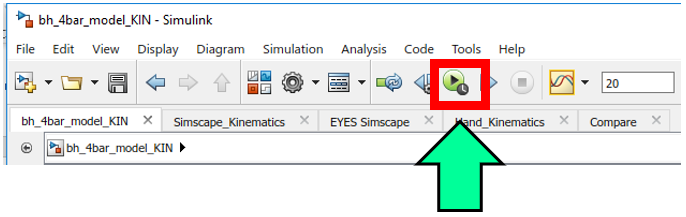

# Helper Functions

**Calculate mass:**

function mass = LOC_calc_mass(L, H, W, density)    
         mass = L*H*W*density;
end

**Calculate Inertia about the centre of mass:**

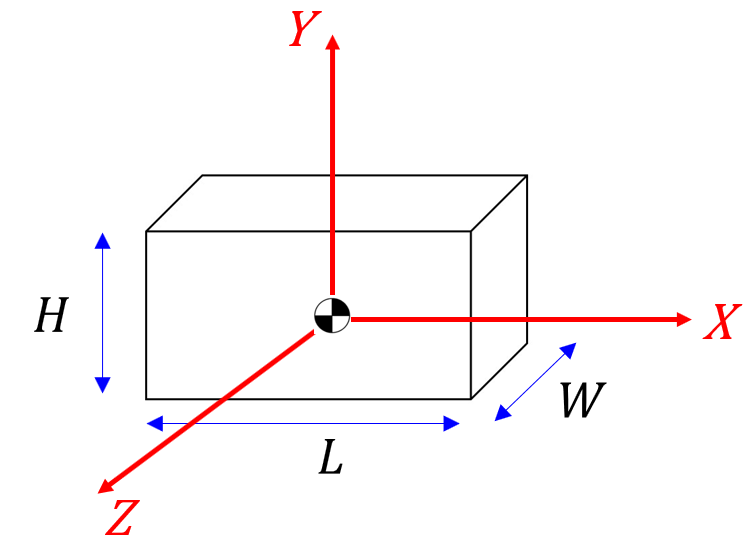

function IG = LOC_calc_IG(L, H, W, density)    
   mass = LOC_calc_mass(L, H, W, density);
   
   IG   = (1/12) * mass * (L^2 + H^2);
end